% === RN黑洞轨道：解决步长过小报错版 ===
clear; clc;

% 1. 物理参数
M = 1; Q = 0.5;               
r_h = M + sqrt(M^2 - Q^2);    % 视界半径 (R+)

% 2. 初始条件 (设定在 2.5 * r_h 处)
r_0 = 2.5 * r_h;              
L = 3.49 * M;                 
E = 0.95;                     

f_func = @(r) 1 - 2*M./r + Q^2./r.^2;
f_0 = f_func(r_0);
term = (E^2/f_0 - 1 - L^2/r_0^2) / f_0;
pr_0 = sqrt(max(0, term));    

u0 = [0; r_0; pi/2; 0; -E; pr_0; 0; L];

% 3. 符号生成方程 (郑氏架构)
syms t r th ph pt pr pth pph tau real
f_s = 1 - 2*M/r + Q^2/r^2;
g_up = diag([-1/f_s, f_s, 1/r^2, 1/(r^2*sin(th)^2)]);
H_sym = 0.5 * [pt pr pth pph] * g_up * [pt; pr; pth; pph];
vars = [t; r; th; ph; pt; pr; pth; pph];
eqs = [diff(H_sym,pt); diff(H_sym,pr); diff(H_sym,pth); diff(H_sym,pph); ...
      -diff(H_sym,t); -diff(H_sym,r); -diff(H_sym,th); -diff(H_sym,ph)];
odefun = matlabFunction(eqs, 'Vars', {tau, vars});

% 4. 数值积分 (添加 Events 选项防止步长报错)
% 当 r 接近 r_h 时，停止计算
options = odeset('RelTol', 1e-9, 'AbsTol', 1e-12, 'MaxStep', 0.1, ...
                 'Events', @(t,u) stop_at_horizon(t, u, r_h));

fprintf('开始积分... 如果粒子坠入视界，程序将自动停止。\n');

开始积分... 如果粒子坠入视界，程序将自动停止。


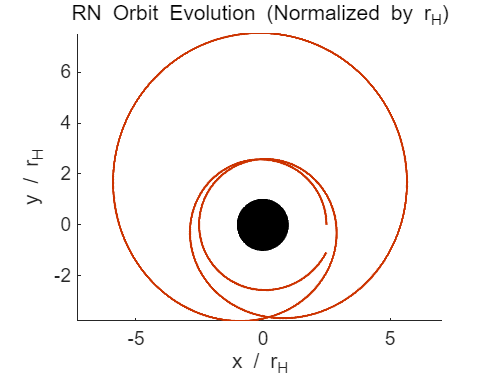

[~, sol] = ode45(odefun, [0 300], u0, options);

% 5. 绘图 (以 r_h 为单位归一化坐标)
r_norm = real(sol(:, 2)) ./ r_h; 
phi_sol = real(sol(:, 4));
x_norm = r_norm .* cos(phi_sol);
y_norm = r_norm .* sin(phi_sol);

fig = figure('Color', 'w'); ax = axes('Parent', fig); hold(ax, 'on');

% 绘制轨道
line(x_norm, y_norm, 'Color', [0.8 0.2 0], 'LineWidth', 1.2, 'Parent', ax);

% 绘制视界 (半径为 1)
rectangle('Position', [-1, -1, 2, 2], 'Curvature', [1, 1], ...
          'FaceColor', 'k', 'Parent', ax);

% 坐标修饰
axis(ax, 'equal'); grid(ax, 'off');
xlabel(ax, 'x / r_H'); ylabel(ax, 'y / r_H');
title(ax, 'RN Orbit Evolution (Normalized by r_H)');


% --- 事件检测函数 ---

function [value, isterminal, direction] = stop_at_horizon(~, u, r_h)
    % 当 r < 1.001 * r_h 时，停止积分
    value = u(2) - 1.001 * r_h; 
    isterminal = 1;  % 停止积分
    direction = -1; % 仅当从外向内运动时触发
end